**ECE537 Programming Assignment 2**

Yuan Sui

1a) Generate N=100 independent sample of two dimensional gaussian vector X

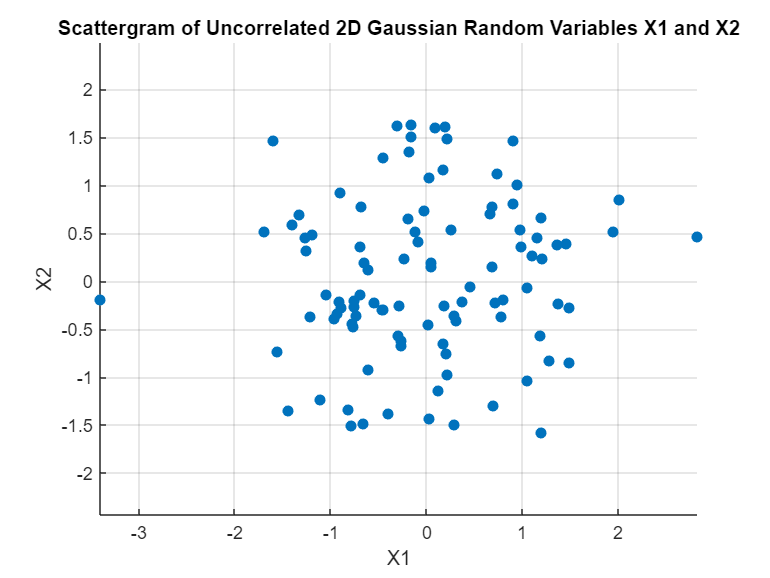

% Number of samples
N = 100;

% Mean and covariance for uncorrelated X1 and X2
mu = [0 0];  % Mean of [X1 X2]
sigma = [1 0; 0 1];  % Covariance matrix for uncorrelated variables (diagonal)

% Generate N samples of the 2D Gaussian random vector
X = mvnrnd(mu, sigma, N);

% Extract X1 and X2
X1 = X(:,1);
X2 = X(:,2);

% Plot scattergram of X1 and X2
scatter(X1, X2, 'filled')
xlabel('X1');
ylabel('X2');
title('Scattergram of Uncorrelated 2D Gaussian Random Variables X1 and X2');
grid on;
axis equal;

Observation: we can see that the distribution forms a circular shape with center around (0,0). This indicate that the expected value is around (0,0) and that X1 and X2 are indepenedent of each other. This observation align with the fact that X1 and X2 have expected value of 0 and they are uncorrelated with each other. 

1b) Generate N=100 independent sample of two dimensional gaussian vector X with different p values

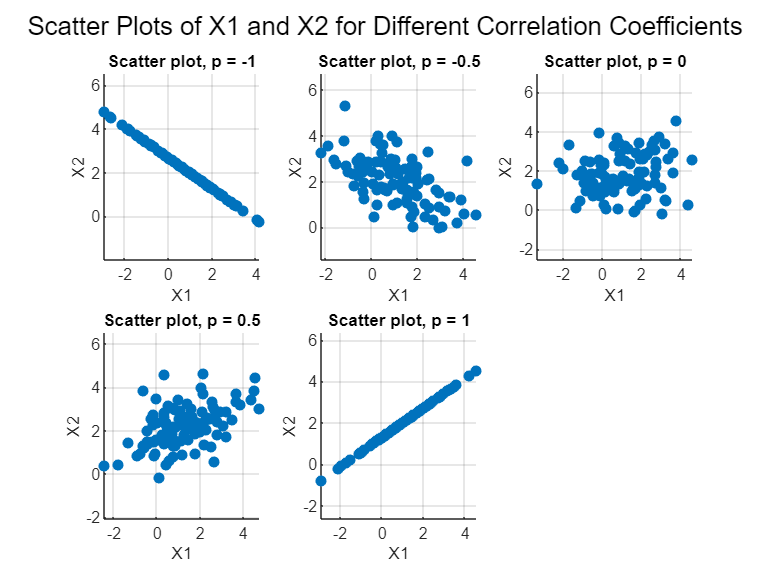

% Number of samples
N = 100;

% Mean values of X1 and X2
mu = [1 2];

% Variance of X1 and X2
var_X1 = 2; % Variance of X1
var_X2 = 1; % Variance of X2

% Different correlation values for p
p_values = [-1, -0.5, 0, 0.5, 1];

% Create figure for multiple plots
figure;

for i = 1:length(p_values)
    % Correlation coefficient p
    p = p_values(i);
    
    % Covariance matrix based on the correlation p
    sigma = [var_X1, p*sqrt(var_X1*var_X2); p*sqrt(var_X1*var_X2), var_X2];
    
    % Generate N samples of the 2D Gaussian random vector
    X = mvnrnd(mu, sigma, N);
    
    % Extract X1 and X2
    X1 = X(:,1);
    X2 = X(:,2);
    
    % Create a subplot for each value of p
    subplot(2, 3, i);
    scatter(X1, X2, 'filled');
    xlabel('X1');
    ylabel('X2');
    title(['Scatter plot, p = ', num2str(p)]);
    grid on;
    axis equal;
end

% Adjust subplot layout
sgtitle('Scatter Plots of X1 and X2 for Different Correlation Coefficients');

Observation: We can tell that the center has now shifted to (1, 2) and the distribution no longer display a circular shape. This tells us that the expected value of X1 and X2 are 1 and 2 respectively. Also, that X1 and X2 are correlated to each other affected by the p value.

1c) Use samples of X in part b) to estimate marginal pdf of X1 with p=0.5. 

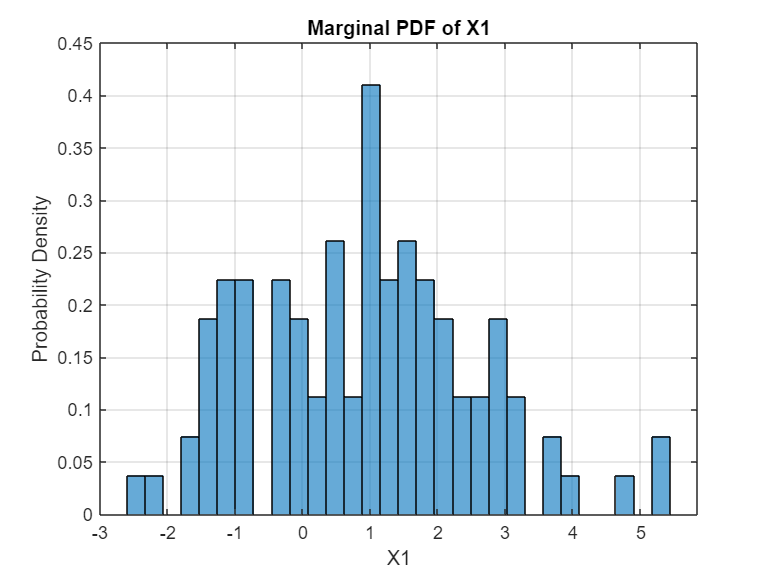

% Number of samples
N = 100;  % Increase sample size for more accurate estimation

% Mean values of X1 and X2
mu = [1 2];

% Variance of X1 and X2
var_X1 = 2; % Variance of X1
var_X2 = 1; % Variance of X2

% Correlation coefficient p
p = 0.5;

% Covariance matrix based on the correlation p
sigma = [var_X1, p*sqrt(var_X1*var_X2); p*sqrt(var_X1*var_X2), var_X2];

% Generate N samples of the 2D Gaussian random vector
X = mvnrnd(mu, sigma, N);

% Extract X1
X1 = X(:,1);

% Plot histogram of X1 (Marginal PDF)
figure;
histogram(X1, 30, 'Normalization', 'pdf');
xlabel('X1');
ylabel('Probability Density');
title('Marginal PDF of X1');
grid on;


% Estimate the expected value (mean) and variance of X1
mean_X1 = mean(X1);
var_X1_estimated = var(X1);

% Display the estimated mean and variance
disp(['Estimated Expected Value (Mean) of X1: ', num2str(mean_X1)]);

Estimated Expected Value (Mean) of X1: 0.94168


disp(['Estimated Variance of X1: ', num2str(var_X1_estimated)]);

Estimated Variance of X1: 2.7446


 We can estimate the marginal pdf to be a gaussian distribution with mean = 1 and variance =2

2a) Does (1/n)(Sn) converge? If so what is the limit?

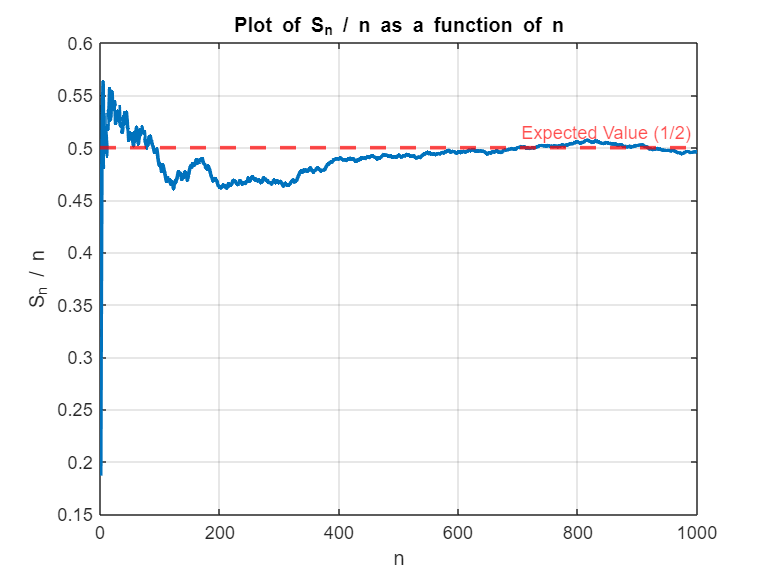

% Number of trials (n values from 1 to 1000)
n_max = 1000;

% Generate n_max independent uniform random variables Xi in [0, 1]
X = rand(1, n_max);

% Initialize array to store Sn/n values
Sn_over_n = zeros(1, n_max);

% Compute Sn and Sn/n for each n
S_n = 0;
for n = 1:n_max
    S_n = S_n + X(n);      % Summation of Xi
    Sn_over_n(n) = S_n / n; % Compute Sn/n
end

% Plot Sn/n as a function of n
figure;
plot(1:n_max, Sn_over_n, 'LineWidth', 2);
xlabel('n');
ylabel('S_n / n');
title('Plot of S_n / n as a function of n');
grid on;

% Reference line at 1/2 (expected value of a uniform [0,1] random variable)
hold on;
yline(0.5, '--r', 'Expected Value (1/2)', 'LineWidth', 2);

We know Xi is a uniform random variable distributed in the interval [0,1]. Therefore, we know that E[Xi] = 1/2. By the law of large numbers, Sn/n = (sum of n Xi's)/n should converge to E[Xi] as n increases. This is reflected in the graph above as the value of Sn/n converge to 1/2 as n increases. 

2b) Let n = 100, Define random variable Z100. Generate 1000 samples of Z100 and plot histogram.

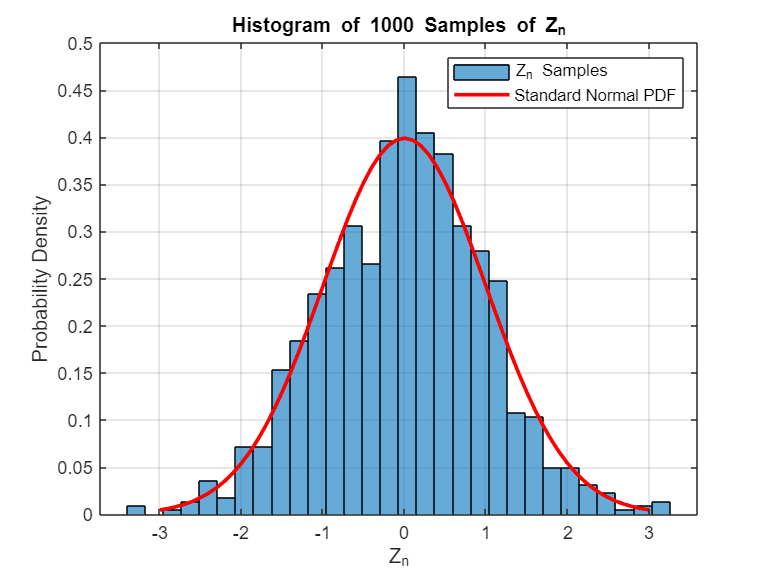

% Number of samples (1000 trials)
num_samples = 1000;

% Number of uniform random variables to sum (n = 100)
n = 100;

% Generate 1000 samples of 100 independent uniform random variables in [0, 1]
X = rand(num_samples, n);

% Compute Sn for each sample (sum along rows)
Sn = sum(X, 2);

% Compute Zn for each sample
Zn = (Sn - 50) / sqrt(100/12);

% Plot histogram of Zn
figure;
histogram(Zn, 30, 'Normalization', 'pdf');
xlabel('Z_n');
ylabel('Probability Density');
title('Histogram of 1000 Samples of Z_n');
grid on;

% Overlay the standard normal distribution for comparison
hold on;
x_vals = -3:0.1:3;  % Range of x values for normal PDF
normal_pdf = normpdf(x_vals, 0, 1);  % Standard normal PDF
plot(x_vals, normal_pdf, 'r', 'LineWidth', 2);  % Plot the normal curve
legend('Z_n Samples', 'Standard Normal PDF');

2c) We can tell that Z100 is a gaussian distribution with mean of 0 and variance of 1. From equation we know that S100 have expected value of 100(1/2) = 50 and variance of 100(1/12) = 100/12. So by defining Z100 as (S100-50)/sqrt(100/12), we are precisely converting S100 into a gaussian distribution of 0 mean and 1 variance. This matches with the observation from the histogram of 2b). 

2d) Use simulated data to estimate the expected value and variance of Z100. 

% Number of samples (1000 trials)
num_samples = 1000;

% Number of uniform random variables to sum (n = 100)
n = 100;

% Generate 1000 samples of 100 independent uniform random variables in [0, 1]
X = rand(num_samples, n);

% Compute Sn for each sample (sum along rows)
Sn = sum(X, 2);

% Compute Z100 for each sample
Z100 = (Sn - 50) / sqrt(100/12);

% Estimate the expected value (mean) of Z100
expected_value_Z100 = mean(Z100);

% Estimate the variance of Z100
variance_Z100 = var(Z100);

% Display the results
disp(['Estimated Expected Value of Z100: ', num2str(expected_value_Z100)]);

Estimated Expected Value of Z100: -0.011029


disp(['Estimated Variance of Z100: ', num2str(variance_Z100)]);

Estimated Variance of Z100: 1.0536


Estimated expected value and variance matches the theoretical value derived in 2c). 